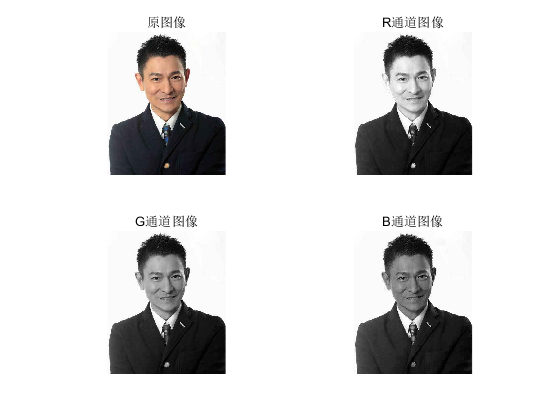

%读取图像
I=imread('01-刘德华.jpg');
figure
subplot(2,2,1)
imshow(I);
title("原图像");
subplot(2,2,2)
imshow(I(:,:,1));
title("R通道图像");
subplot(2,2,3)
imshow(I(:,:,2));
title("G通道图像");
subplot(2,2,4)
imshow(I(:,:,3));
title("B通道图像");

disp("R通道均值为：")

R通道均值为：


Rmax=max(I(:,:,1),[],'all')

Rmax = uint8
255

disp("G通道均值为：")

G通道均值为：


Gmin=min(I(:,:,2),[],'all')

Gmin = uint8
0

disp("B通道均值为：")

B通道均值为：


Bmean=mean(I(:,:,3),'all')

Bmean = 134.7388

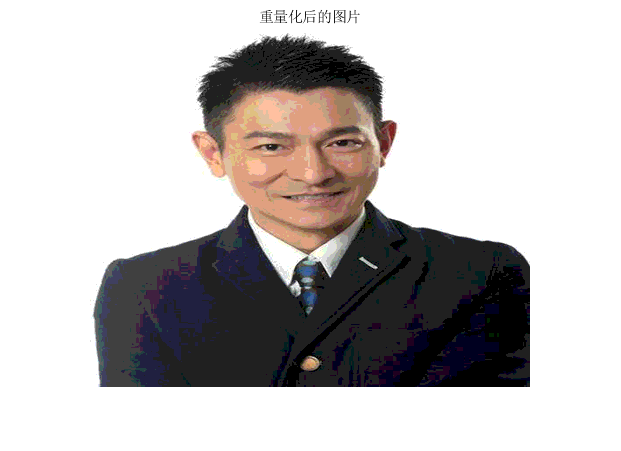

%重采样
row=358;
col=441;
temp=zeros(row,col,3);
I_resize=imresize(I,[row,col]);
%重量化
I_resize=floor(I_resize/32)*32;
%绘图
figure
imshow(I_resize);
title("重量化后的图片")

%保存
imwrite(I_resize,'重量化后的图片.jpg','jpg');